Initialization

% clear all;
% close all ;
% clc;
% base_dir="..\data\"; 
% cd(base_dir);

Data Extraction

subject="p2s1"

subject = "p2s1"

comparison_mode="rs_pskf"

comparison_mode = "rs_pskf"

op=readtable("csv\" + subject + "_switched.csv");

transpose(op.Properties.VariableNames);
%mocap=readtable("p1s1_mocap_2d_keypoints.csv");
mocap=readtable("csv\" + subject + "_mocap_2d.csv");
transpose(mocap.Properties.VariableNames);
kf=readtable("csv\" + subject + "_processed_switched_kf.csv");
errors_x=[];
errors_y=[];
keypoint_names=[];
start_frame=10;
total_frame=height(op);

Graphing keypoints

Neck

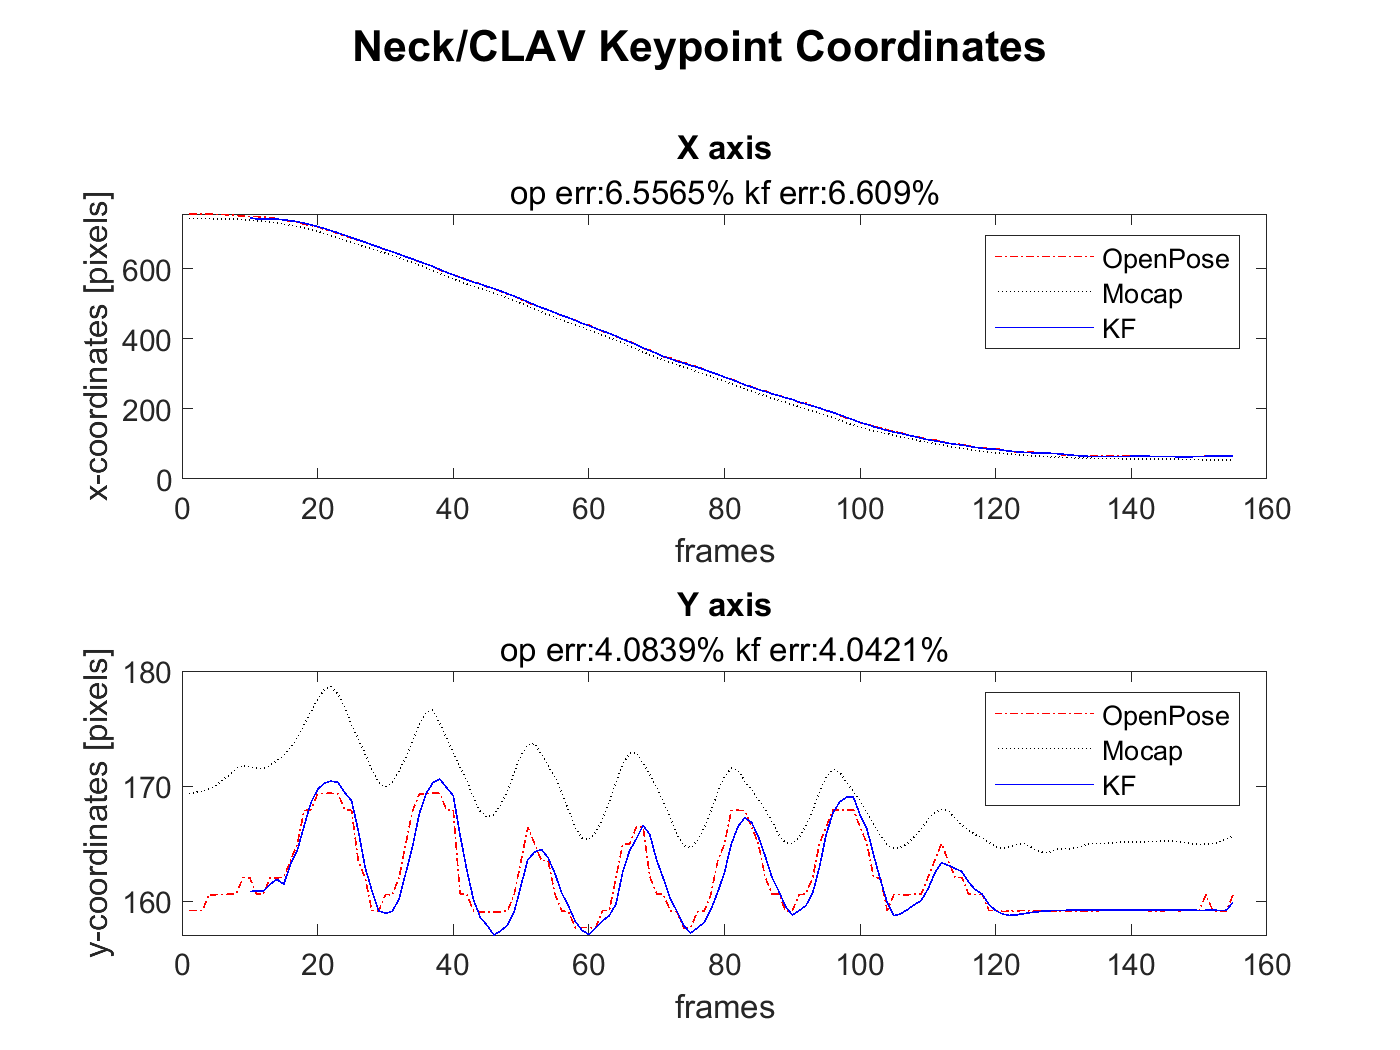

keypoint_op=[op.neck_x op.neck_y];
keypoint_mocap=[mocap.CLAV_x mocap.CLAV_y];
keypoint_kf=[kf.neck_x kf.neck_y];
kf_x=keypoint_kf(:,1);
kf_y=keypoint_kf(:,2);
op_x=keypoint_op(:,1);
op_y=keypoint_op(:,2);
mocap_x=keypoint_mocap(:,1);
mocap_y=keypoint_mocap(:,2);


%plotting
figure;
sgtitle('Neck/CLAV Keypoint Coordinates','FontSize',13,'FontWeight','bold') 
subplot(2,1,1);
plot(op_x,'r-.')
hold on;
plot(mocap_x,'k:')
plot(start_frame:total_frame, kf_x,'b-')
legend('OpenPose', 'Mocap','KF')
all_err=(abs(op_x-mocap_x)./mocap_x)*100;
err=mean(all_err);
all_err_kf=(abs(kf_x-mocap_x(start_frame:end))./mocap_x(start_frame:end))*100;
err_kf=mean(all_err_kf);
errors_x=[errors_x; err err_kf];
subtitle("op err:"+err+"% kf err:" + err_kf +"%")
title("X axis")

ylabel('x-coordinates [pixels]')
xlabel('frames')
hold off;
%axis square

subplot(2,1,2);
plot(op_y,'r-.')
hold on;
plot(mocap_y,'k:')
plot(start_frame:total_frame, kf_y,'b-')
legend('OpenPose', 'Mocap','KF')
all_err=(abs(op_y-mocap_y)./mocap_y)*100;
err=mean(all_err);
all_err_kf=(abs(kf_y-mocap_y(start_frame:end))./mocap_y(start_frame:end))*100;
err_kf=mean(all_err_kf);
errors_y=[errors_y; err err_kf];
subtitle("op err:"+err+"% kf err:" + err_kf +"%")
xlabel('frames')
ylabel('y-coordinates [pixels]')
title("Y axis")
hold off;
%axis square

f = gcf;
fig_filename='figures\' + subject +'_'+ comparison_mode+'_neck-clav.png';
exportgraphics(f,fig_filename,'Resolution',300)

Neck

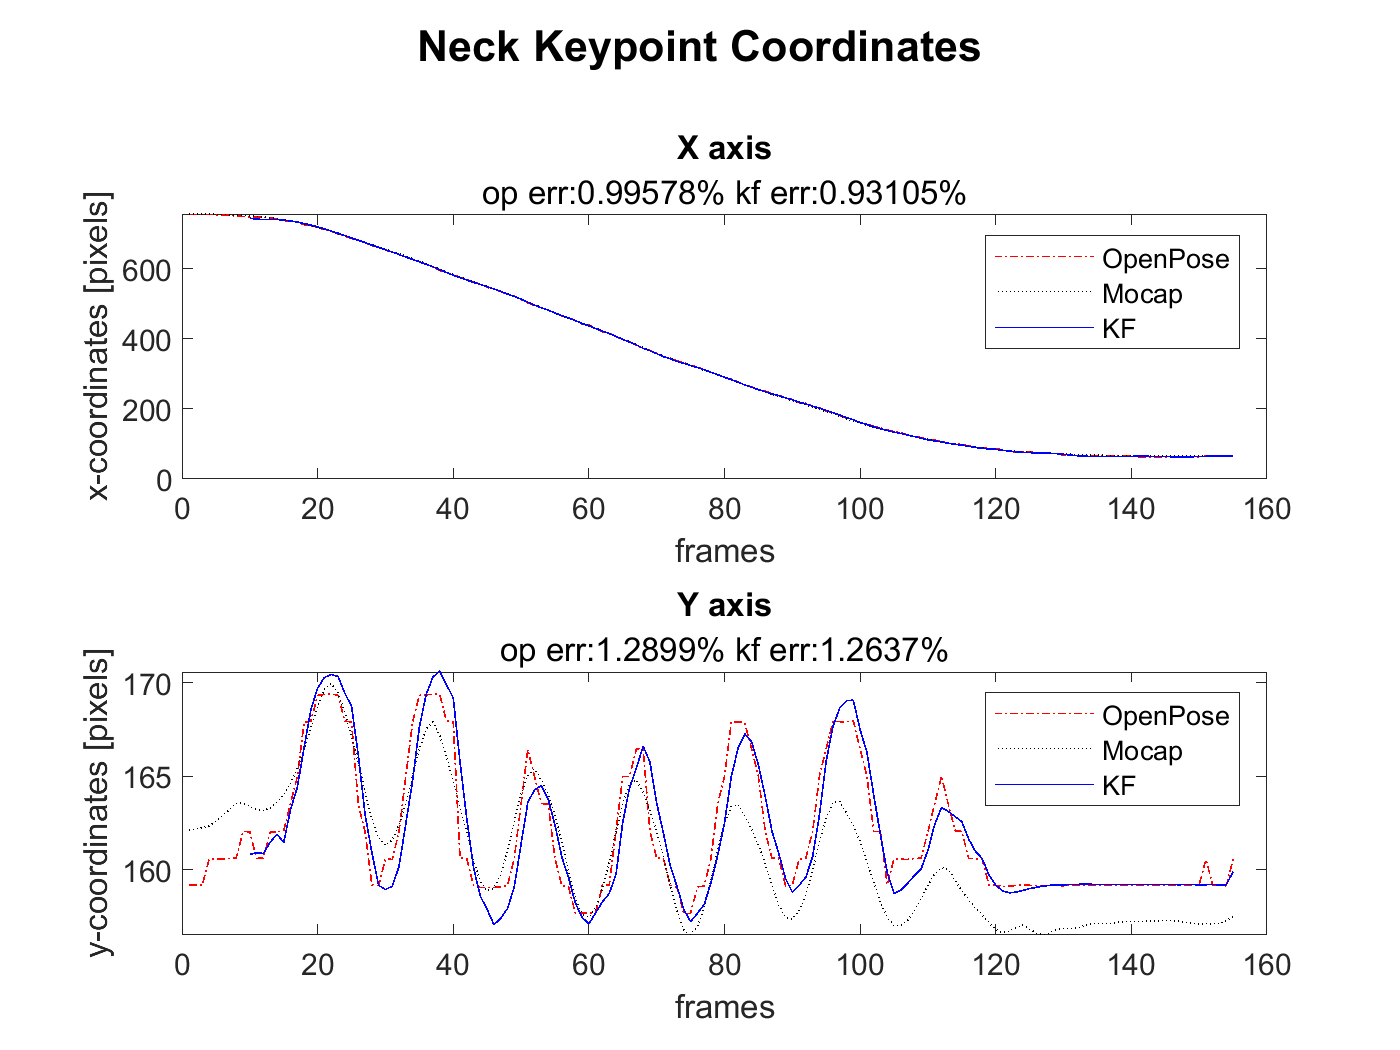

keypoint_op=[op.neck_x op.neck_y];
keypoint_mocap=[mocap.MIDDLENECK_x mocap.MIDDLENECK_y];
keypoint_kf=[kf.neck_x kf.neck_y];
kf_x=keypoint_kf(:,1);
kf_y=keypoint_kf(:,2);
op_x=keypoint_op(:,1);
op_y=keypoint_op(:,2);
mocap_x=keypoint_mocap(:,1);
mocap_y=keypoint_mocap(:,2);


%plotting
figure;
sgtitle('Neck Keypoint Coordinates','FontSize',13,'FontWeight','bold') 
subplot(2,1,1);
plot(op_x,'r-.')
hold on;
plot(mocap_x,'k:')
plot(start_frame:total_frame, kf_x,'b-')
legend('OpenPose', 'Mocap','KF')
all_err=(abs(op_x-mocap_x)./mocap_x)*100;
err=mean(all_err);
all_err_kf=(abs(kf_x-mocap_x(start_frame:end))./mocap_x(start_frame:end))*100;
err_kf=mean(all_err_kf);
errors_x=[errors_x; err err_kf];
subtitle("op err:"+err+"% kf err:" + err_kf +"%")
title("X axis")

ylabel('x-coordinates [pixels]')
xlabel('frames')
hold off;
%axis square

subplot(2,1,2);
plot(op_y,'r-.')
hold on;
plot(mocap_y,'k:')
plot(start_frame:total_frame, kf_y,'b-')
legend('OpenPose', 'Mocap','KF')
all_err=(abs(op_y-mocap_y)./mocap_y)*100;
err=mean(all_err);
all_err_kf=(abs(kf_y-mocap_y(start_frame:end))./mocap_y(start_frame:end))*100;
err_kf=mean(all_err_kf);
errors_y=[errors_y; err err_kf];
subtitle("op err:"+err+"% kf err:" + err_kf +"%")
xlabel('frames')
ylabel('y-coordinates [pixels]')
title("Y axis")
hold off;
%axis square
f = gcf;
fig_filename='figures\' + subject +'_'+ comparison_mode+'_neck.png';
exportgraphics(f,fig_filename,'Resolution',300)

spine_hip

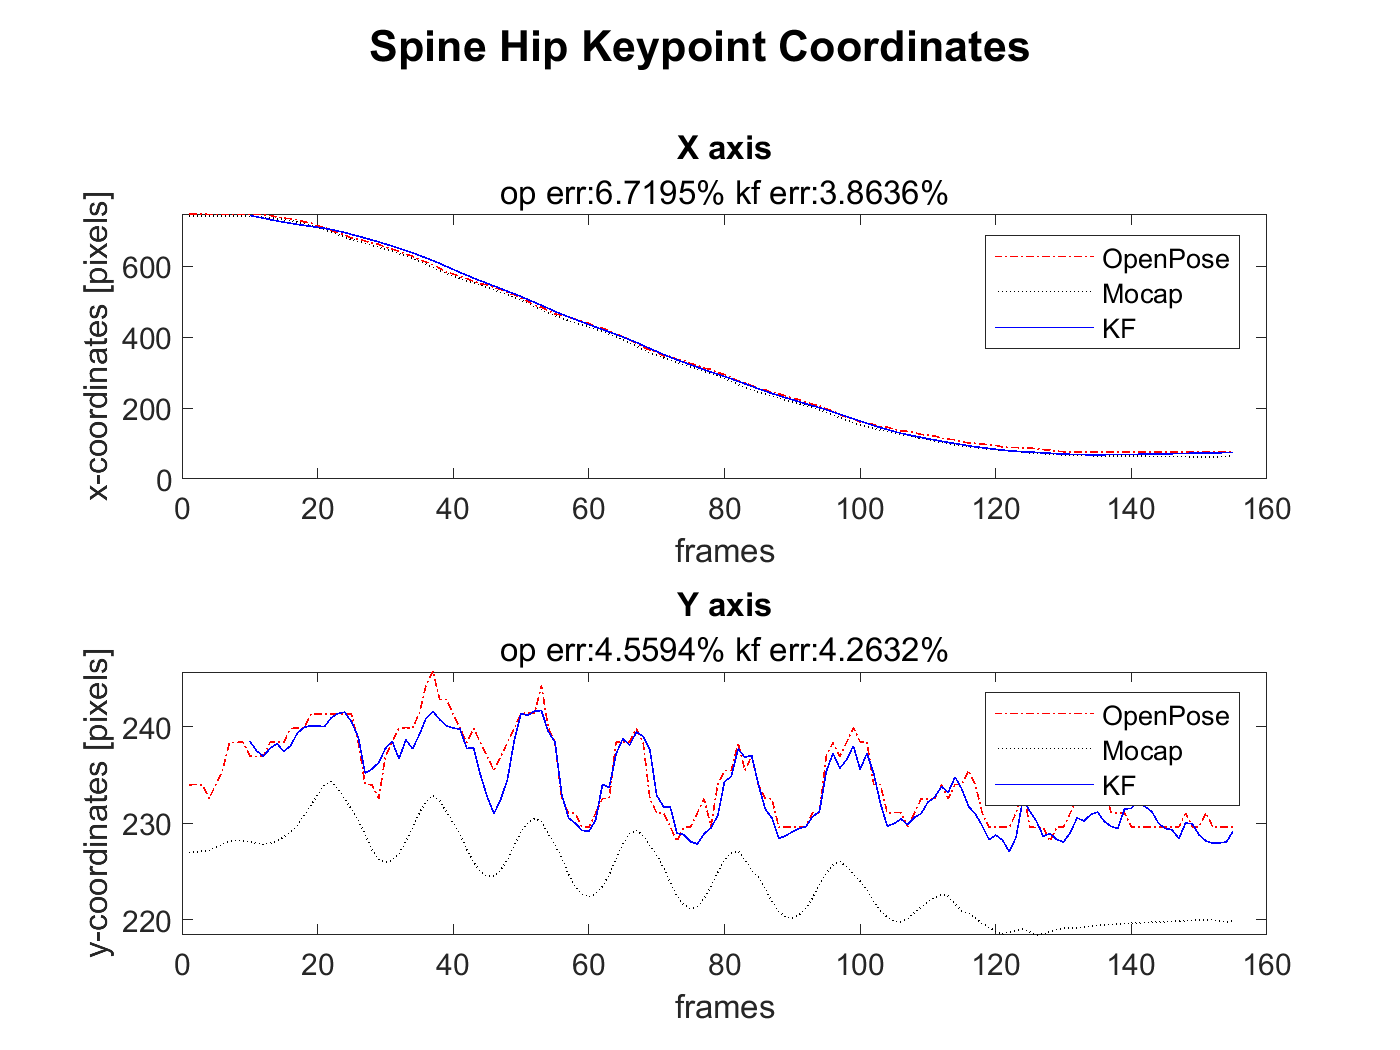

keypoint_op=[op.spine_hip_x op.spine_hip_y];
keypoint_mocap=[mocap.SPINEHIP_x mocap.SPINEHIP_y];
keypoint_kf=[kf.spine_hip_x kf.spine_hip_y];
kf_x=keypoint_kf(:,1);
kf_y=keypoint_kf(:,2);
op_x=keypoint_op(:,1);
op_y=keypoint_op(:,2);
mocap_x=keypoint_mocap(:,1);
mocap_y=keypoint_mocap(:,2);

%plotting
figure;
sgtitle('Spine Hip Keypoint Coordinates','FontSize',13,'FontWeight','bold') 
subplot(2,1,1);
plot(op_x,'r-.')
hold on;
plot(mocap_x,'k:')
plot(start_frame:total_frame, kf_x,'b-')
legend('OpenPose', 'Mocap','KF')
all_err=(abs(op_x-mocap_x)./mocap_x)*100;
err=mean(all_err);
all_err_kf=(abs(kf_x-mocap_x(start_frame:end))./mocap_x(start_frame:end))*100;
err_kf=mean(all_err_kf);
errors_x=[errors_x; err err_kf];
title("X axis")
subtitle("op err:"+err+"% kf err:" + err_kf +"%")

title("X axis")
xlabel('frames')
ylabel('x-coordinates [pixels]')
hold off;

subplot(2,1,2);
plot(op_y,'r-.')
hold on;
plot(mocap_y,'k:')
plot(start_frame:total_frame, kf_y,'b-')
legend('OpenPose', 'Mocap','KF')
all_err=(abs(op_y-mocap_y)./mocap_y)*100;
err=mean(all_err);
all_err_kf=(abs(kf_y-mocap_y(start_frame:end))./mocap_y(start_frame:end))*100;
err_kf=mean(all_err_kf);
errors_y=[errors_y; err err_kf];
subtitle("op err:"+err+"% kf err:" + err_kf +"%")
xlabel('frames')
title("Y axis")
ylabel('y-coordinates [pixels]')
hold off;

f = gcf;
fig_filename='figures\' + subject +'_'+ comparison_mode+'_spine-hip.png';
exportgraphics(f,fig_filename,'Resolution',300)

right hip

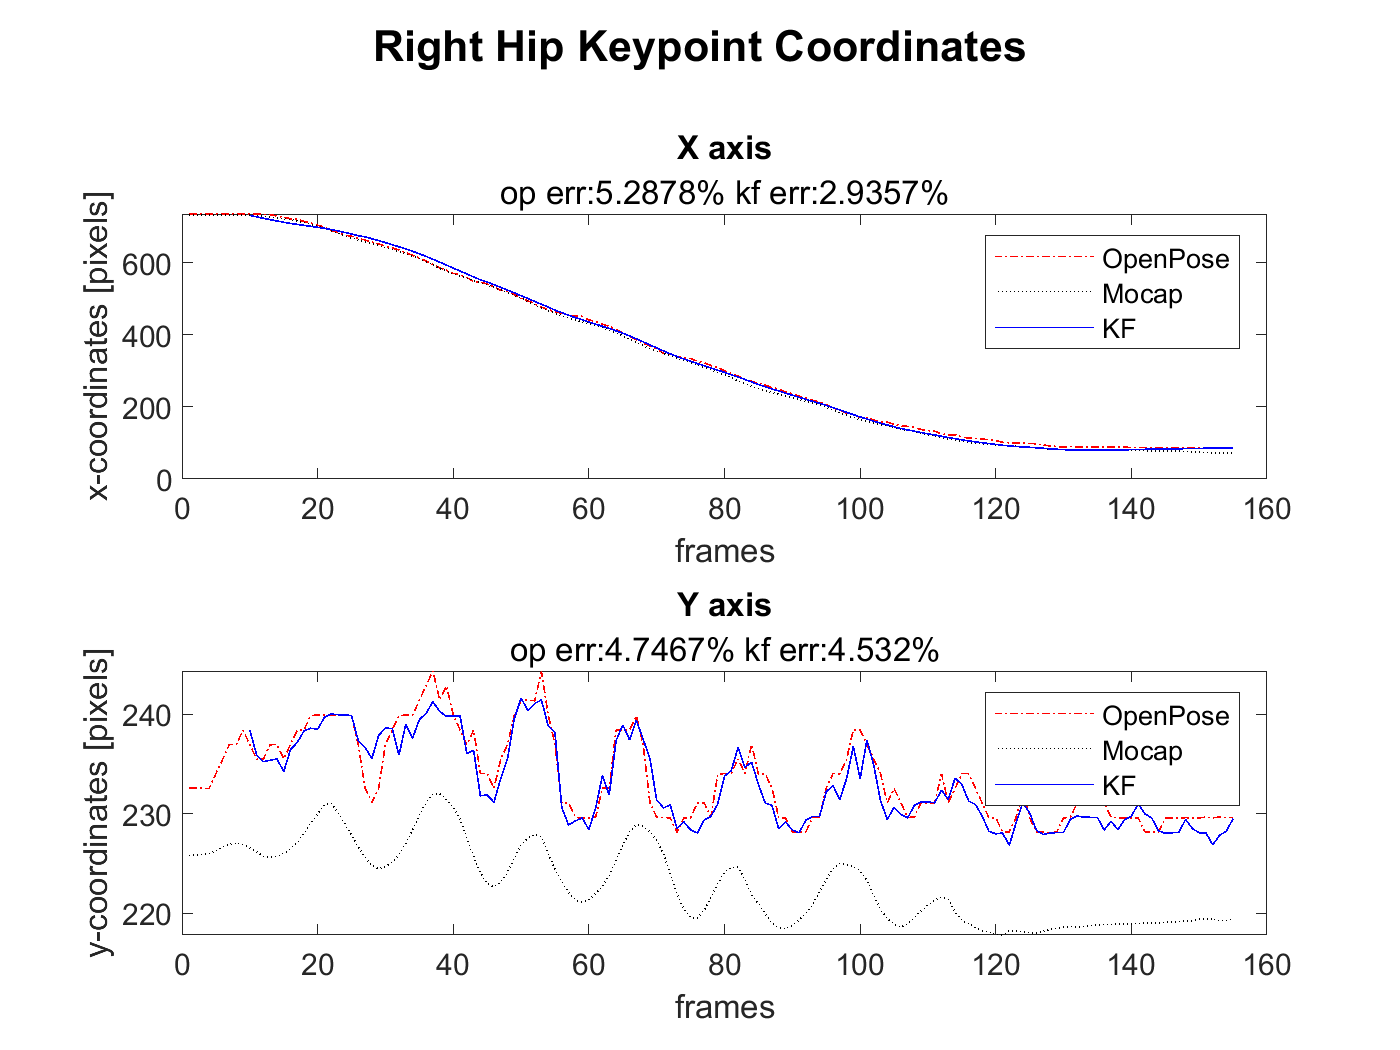

keypoint_op=[op.r_hip_x op.r_hip_y];
keypoint_mocap=[mocap.RASI_x mocap.RASI_y];
keypoint_kf=[kf.r_hip_x kf.r_hip_y];
kf_x=keypoint_kf(:,1);
kf_y=keypoint_kf(:,2);
op_x=keypoint_op(:,1);
op_y=keypoint_op(:,2);
mocap_x=keypoint_mocap(:,1);
mocap_y=keypoint_mocap(:,2);

%plotting
figure;
sgtitle('Right Hip Keypoint Coordinates','FontSize',13,'FontWeight','bold') 
subplot(2,1,1);
plot(op_x,'r-.')
hold on;
plot(mocap_x,'k:')
plot(start_frame:total_frame, kf_x,'b-')
legend('OpenPose', 'Mocap','KF')
all_err=(abs(op_x-mocap_x)./mocap_x)*100;
err=mean(all_err);
all_err_kf=(abs(kf_x-mocap_x(start_frame:end))./mocap_x(start_frame:end))*100;
err_kf=mean(all_err_kf);
errors_x=[errors_x; err err_kf];
title("X axis")
subtitle("op err:"+err+"% kf err:" + err_kf +"%")
xlabel('frames')
ylabel('x-coordinates [pixels]')
hold off;

subplot(2,1,2);
plot(op_y,'r-.')
hold on;
plot(mocap_y,'k:')
plot(start_frame:total_frame, kf_y,'b-')
legend('OpenPose', 'Mocap','KF')
all_err=(abs(op_y-mocap_y)./mocap_y)*100;
err=mean(all_err);
all_err_kf=(abs(kf_y-mocap_y(start_frame:end))./mocap_y(start_frame:end))*100;
err_kf=mean(all_err_kf);
errors_y=[errors_y; err err_kf];
subtitle("op err:"+err+"% kf err:" + err_kf +"%")
xlabel('frames')
ylabel('y-coordinates [pixels]')
title("Y axis")
hold off;

f = gcf;
fig_filename='figures\' + subject +'_'+ comparison_mode+'_r-hip.png';
exportgraphics(f,fig_filename,'Resolution',300)

Right Knee

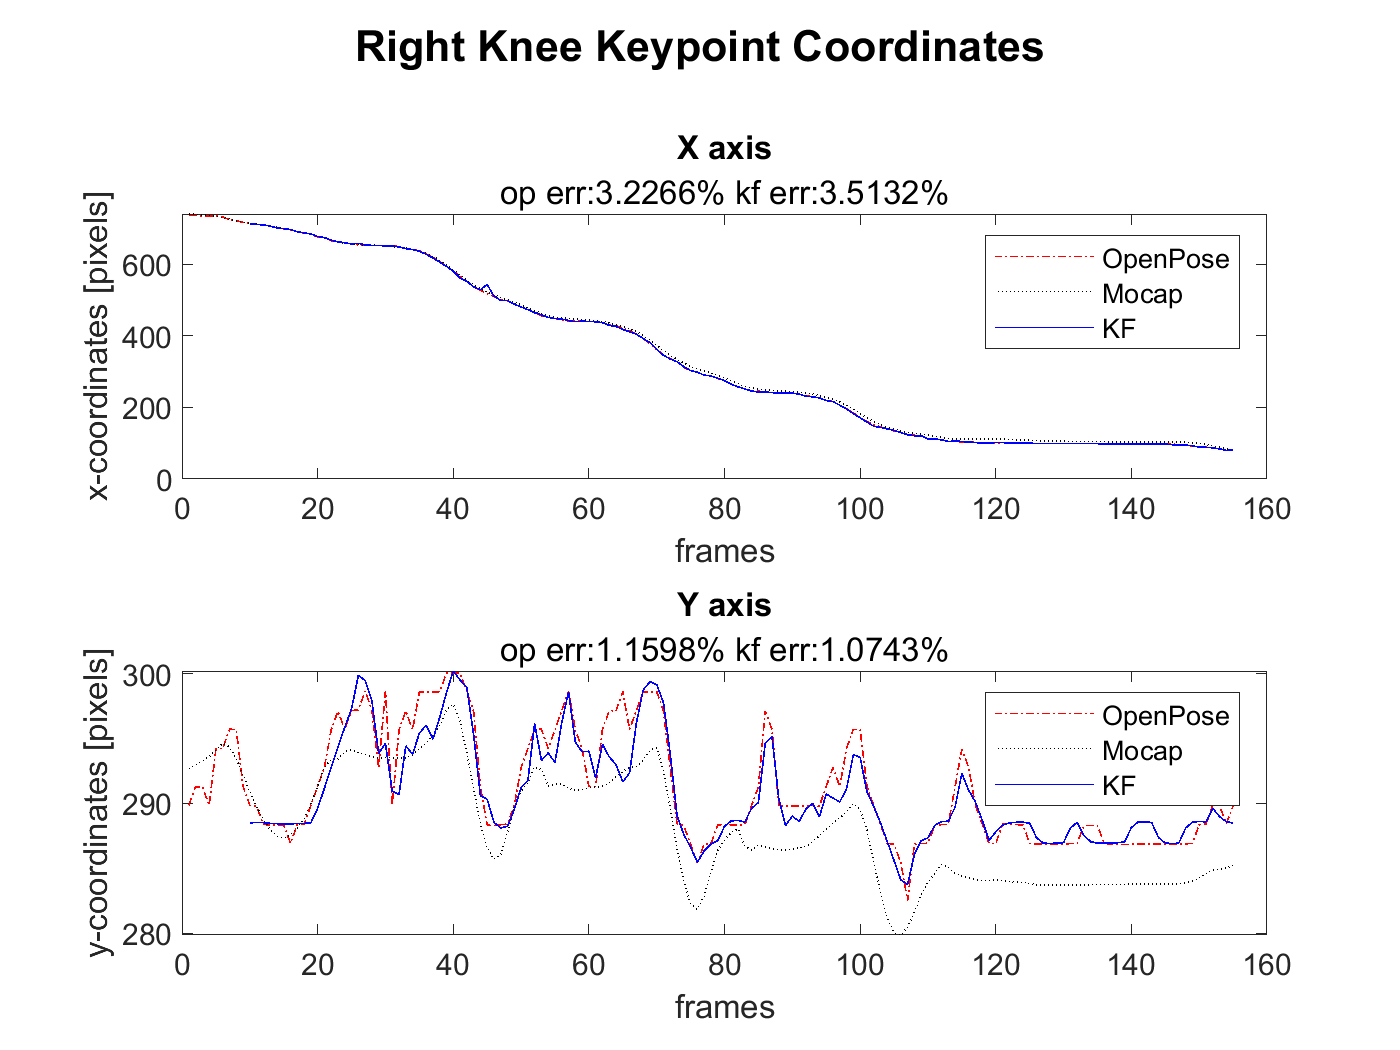

keypoint_op=[op.r_knee_x op.r_knee_y];
keypoint_mocap=[mocap.RKNE_x mocap.RKNE_y];
keypoint_kf=[kf.r_knee_x kf.r_knee_y];
kf_x=keypoint_kf(:,1);
kf_y=keypoint_kf(:,2);
op_x=keypoint_op(:,1);
op_y=keypoint_op(:,2);
mocap_x=keypoint_mocap(:,1);
mocap_y=keypoint_mocap(:,2);

%plotting
figure;
sgtitle('Right Knee Keypoint Coordinates','FontSize',13,'FontWeight','bold') 
subplot(2,1,1);
plot(op_x,'r-.')
hold on;
plot(mocap_x,'k:')
plot(start_frame:total_frame, kf_x,'b-')
legend('OpenPose', 'Mocap','KF')
all_err=(abs(op_x-mocap_x)./mocap_x)*100;
err=mean(all_err);
all_err_kf=(abs(kf_x-mocap_x(start_frame:end))./mocap_x(start_frame:end))*100;
err_kf=mean(all_err_kf);
errors_x=[errors_x; err err_kf];
subtitle("op err:"+err+"% kf err:" + err_kf +"%")
title("X axis")
xlabel('frames')
ylabel('x-coordinates [pixels]')
hold off;

subplot(2,1,2);
plot(op_y,'r-.')
hold on;
plot(mocap_y,'k:')
plot(start_frame:total_frame, kf_y,'b-')
legend('OpenPose', 'Mocap','KF')
all_err=(abs(op_y-mocap_y)./mocap_y)*100;
err=mean(all_err);
all_err_kf=(abs(kf_y-mocap_y(start_frame:end))./mocap_y(start_frame:end))*100;
err_kf=mean(all_err_kf);
errors_y=[errors_y; err err_kf];
subtitle("op err:"+err+"% kf err:" + err_kf +"%")
xlabel('frames')
ylabel('y-coordinates [pixels]')
title("Y axis")
hold off;

f = gcf;
fig_filename='figures\' + subject +'_'+ comparison_mode+'_r-knee.png';
exportgraphics(f,fig_filename,'Resolution',300)

Right ankle

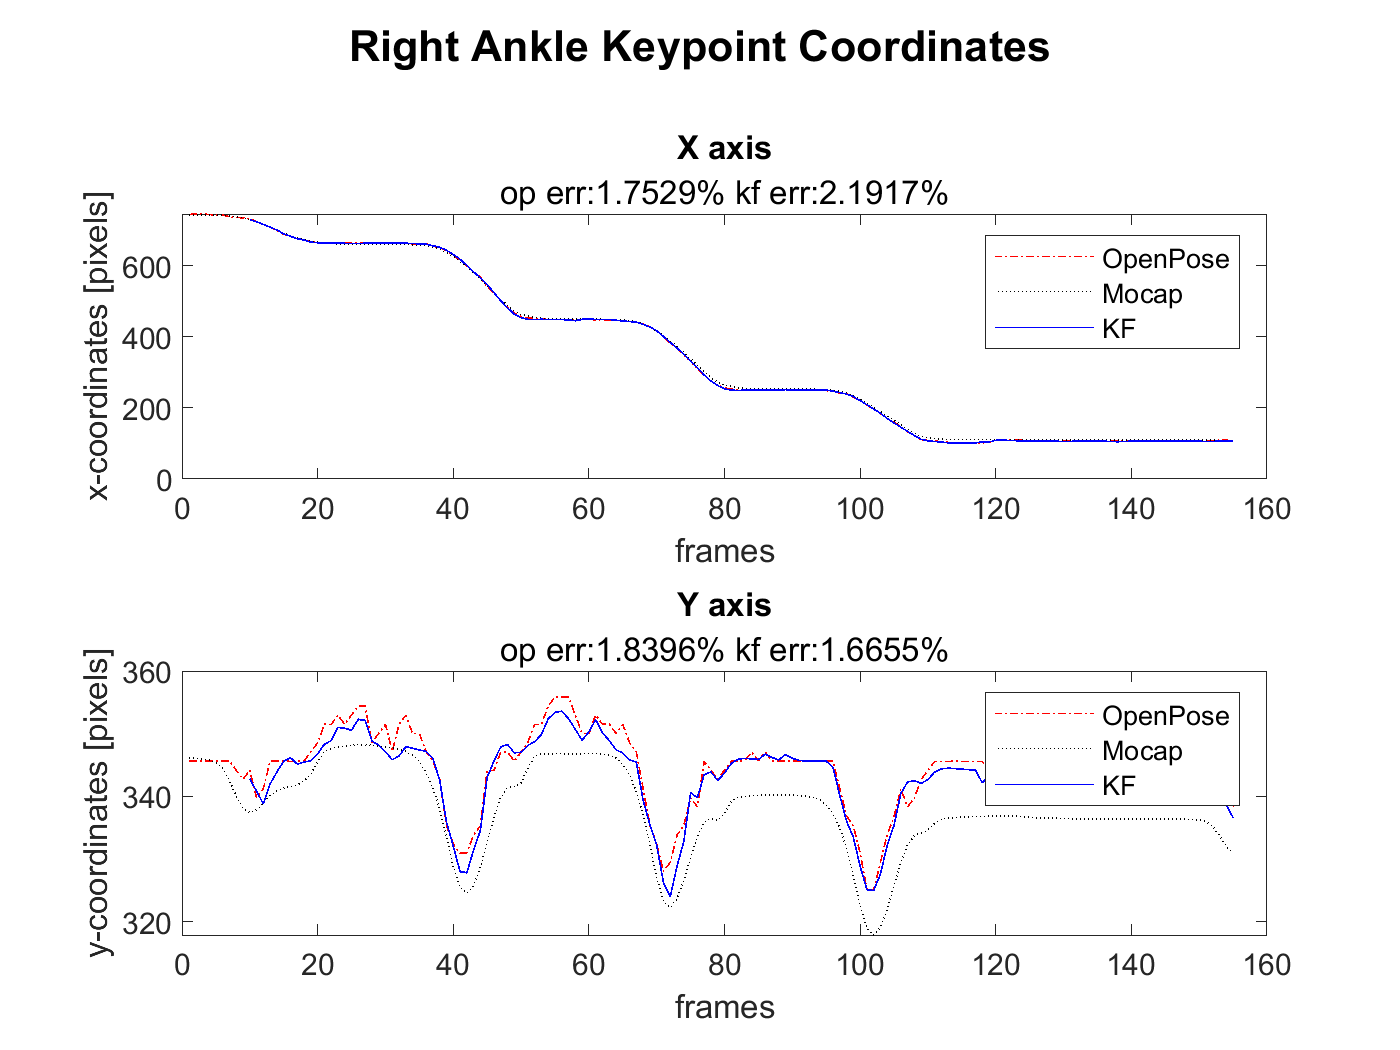

keypoint_op=[op.r_ankle_x op.r_ankle_y];
keypoint_mocap=[mocap.RANK_x mocap.RANK_y];
keypoint_kf=[kf.r_ankle_x kf.r_ankle_y];
kf_x=keypoint_kf(:,1);
kf_y=keypoint_kf(:,2);
op_x=keypoint_op(:,1);
op_y=keypoint_op(:,2);
mocap_x=keypoint_mocap(:,1);
mocap_y=keypoint_mocap(:,2);

%plotting
figure;
sgtitle('Right Ankle Keypoint Coordinates','FontSize',13,'FontWeight','bold') 
subplot(2,1,1);
plot(op_x,'r-.')
hold on;
plot(mocap_x,'k:')
plot(start_frame:total_frame, kf_x,'b-')
legend('OpenPose', 'Mocap','KF')
all_err=(abs(op_x-mocap_x)./mocap_x)*100;
err=mean(all_err);
all_err_kf=(abs(kf_x-mocap_x(start_frame:end))./mocap_x(start_frame:end))*100;
err_kf=mean(all_err_kf);
errors_x=[errors_x; err err_kf];
subtitle("op err:"+err+"% kf err:" + err_kf +"%")
title("X axis")
ylabel('x-coordinates [pixels]')
xlabel('frames')
hold off;

subplot(2,1,2);
plot(op_y,'r-.')
hold on;
plot(mocap_y,'k:')
plot(start_frame:total_frame, kf_y,'b-')
legend('OpenPose', 'Mocap','KF')
all_err=(abs(op_y-mocap_y)./mocap_y)*100;
err=mean(all_err);
all_err_kf=(abs(kf_y-mocap_y(start_frame:end))./mocap_y(start_frame:end))*100;
err_kf=mean(all_err_kf);
errors_y=[errors_y; err err_kf];
subtitle("op err:"+err+"% kf err:" + err_kf +"%")
xlabel('frames')
ylabel('y-coordinates [pixels]')
title("Y axis")
hold off;

f = gcf;
fig_filename='figures\' + subject +'_'+ comparison_mode+'_r-ankle.png';
exportgraphics(f,fig_filename,'Resolution',300)

Right heel

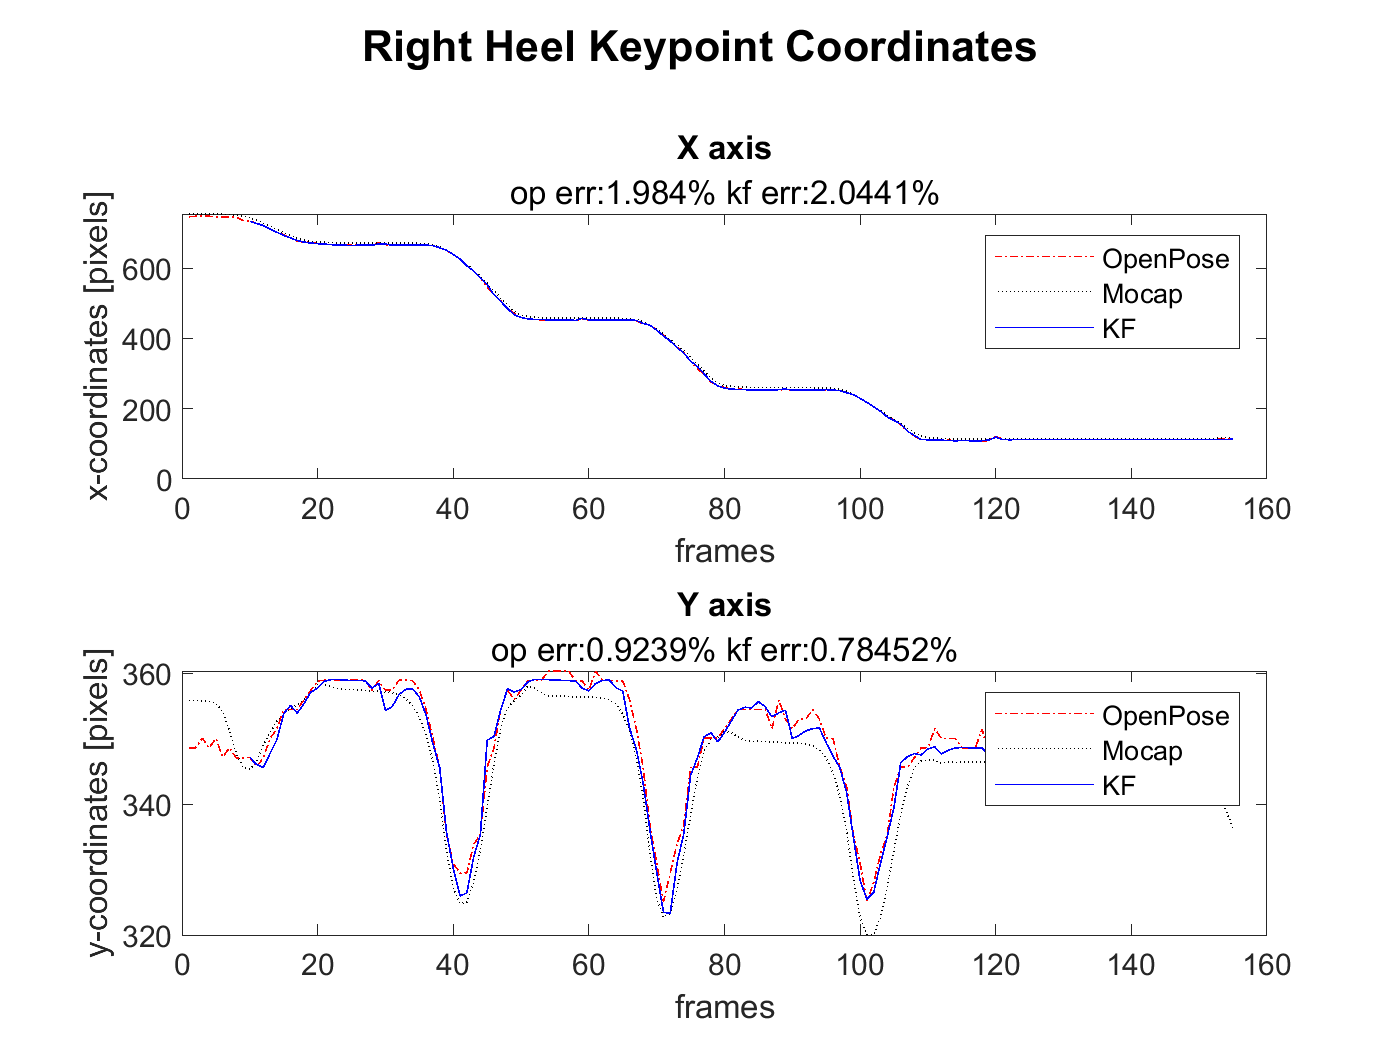

keypoint_op=[op.r_heel_x op.r_heel_y];
keypoint_mocap=[mocap.RHEE_x mocap.RHEE_y];
keypoint_kf=[kf.r_heel_x kf.r_heel_y];
kf_x=keypoint_kf(:,1);
kf_y=keypoint_kf(:,2);
op_x=keypoint_op(:,1);
op_y=keypoint_op(:,2);
mocap_x=keypoint_mocap(:,1);
mocap_y=keypoint_mocap(:,2);

%plotting
figure;
sgtitle('Right Heel Keypoint Coordinates','FontSize',13,'FontWeight','bold') 
subplot(2,1,1);
plot(op_x,'r-.')
hold on;
plot(mocap_x,'k:')
plot(start_frame:total_frame, kf_x,'b-')
legend('OpenPose', 'Mocap','KF')
all_err=(abs(op_x-mocap_x)./mocap_x)*100;
err=mean(all_err);
all_err_kf=(abs(kf_x-mocap_x(start_frame:end))./mocap_x(start_frame:end))*100;
err_kf=mean(all_err_kf);
errors_x=[errors_x; err err_kf];
subtitle("op err:"+err+"% kf err:" + err_kf +"%")
title("X axis")
xlabel('frames')
ylabel('x-coordinates [pixels]')
hold off;

subplot(2,1,2);
plot(op_y,'r-.')
hold on;
plot(mocap_y,'k:')
plot(start_frame:total_frame, kf_y,'b-')
legend('OpenPose', 'Mocap','KF')
all_err=(abs(op_y-mocap_y)./mocap_y)*100;
err=mean(all_err);
all_err_kf=(abs(kf_y-mocap_y(start_frame:end))./mocap_y(start_frame:end))*100;
err_kf=mean(all_err_kf);
errors_y=[errors_y; err err_kf];
subtitle("op err:"+err+"% kf err:" + err_kf +"%")
xlabel('frames')
ylabel('y-coordinates [pixels]')
title("Y axis")
hold off;
f = gcf;
fig_filename='figures\' + subject +'_'+ comparison_mode+'_r-heel.png';
exportgraphics(f,fig_filename,'Resolution',300)

Left hip

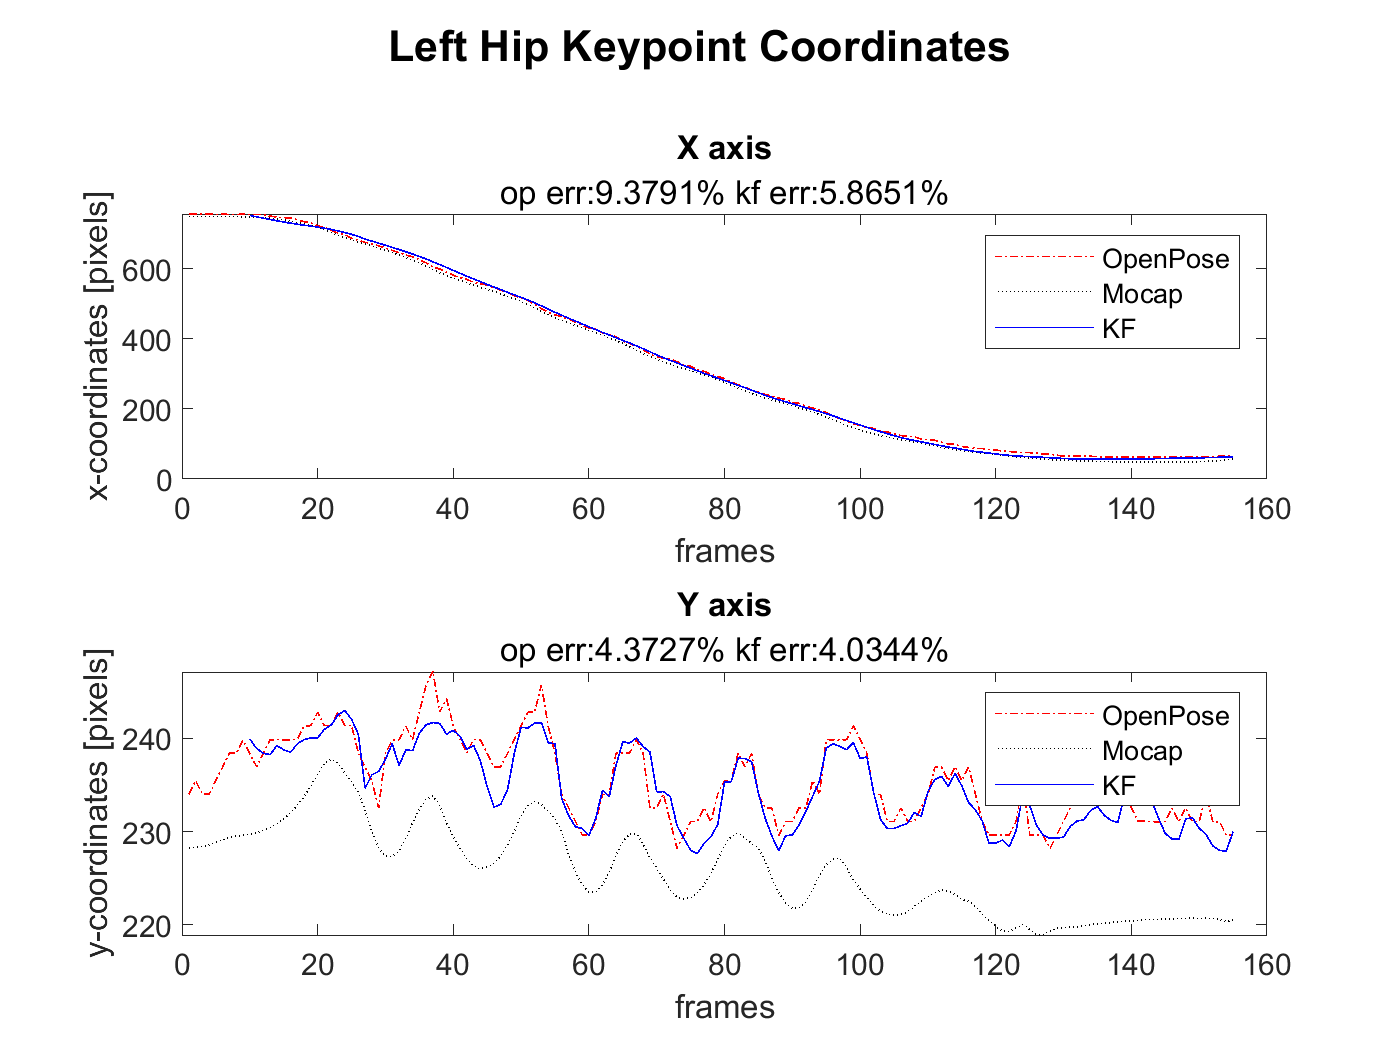

keypoint_op=[op.l_hip_x op.l_hip_y];
keypoint_mocap=[mocap.LASI_x mocap.LASI_y];
keypoint_kf=[kf.l_hip_x kf.l_hip_y];
kf_x=keypoint_kf(:,1);
kf_y=keypoint_kf(:,2);
op_x=keypoint_op(:,1);
op_y=keypoint_op(:,2);
mocap_x=keypoint_mocap(:,1);
mocap_y=keypoint_mocap(:,2);

%plotting
figure;
sgtitle('Left Hip Keypoint Coordinates','FontSize',13,'FontWeight','bold') 
subplot(2,1,1);
plot(op_x,'r-.')
hold on;
plot(mocap_x,'k:')
plot(start_frame:total_frame, kf_x,'b-')
legend('OpenPose', 'Mocap','KF')
all_err=(abs(op_x-mocap_x)./mocap_x)*100;
err=mean(all_err);
all_err_kf=(abs(kf_x-mocap_x(start_frame:end))./mocap_x(start_frame:end))*100;
err_kf=mean(all_err_kf);
errors_x=[errors_x; err err_kf];
subtitle("op err:"+err+"% kf err:" + err_kf +"%")
title("X axis")
xlabel('frames')
ylabel('x-coordinates [pixels]')
hold off;

subplot(2,1,2);
plot(op_y,'r-.')
hold on;
plot(mocap_y,'k:')
plot(start_frame:total_frame, kf_y,'b-')
legend('OpenPose', 'Mocap','KF')
all_err=(abs(op_y-mocap_y)./mocap_y)*100;
err=mean(all_err);
all_err_kf=(abs(kf_y-mocap_y(start_frame:end))./mocap_y(start_frame:end))*100;
err_kf=mean(all_err_kf);
errors_y=[errors_y; err err_kf];
subtitle("op err:"+err+"% kf err:" + err_kf +"%")
xlabel('frames')
ylabel('y-coordinates [pixels]')
title("Y axis")
hold off;

f = gcf;
fig_filename='figures\' + subject +'_'+ comparison_mode+'_l-hip.png' ;
exportgraphics(f,fig_filename,'Resolution',300)

Left Knee

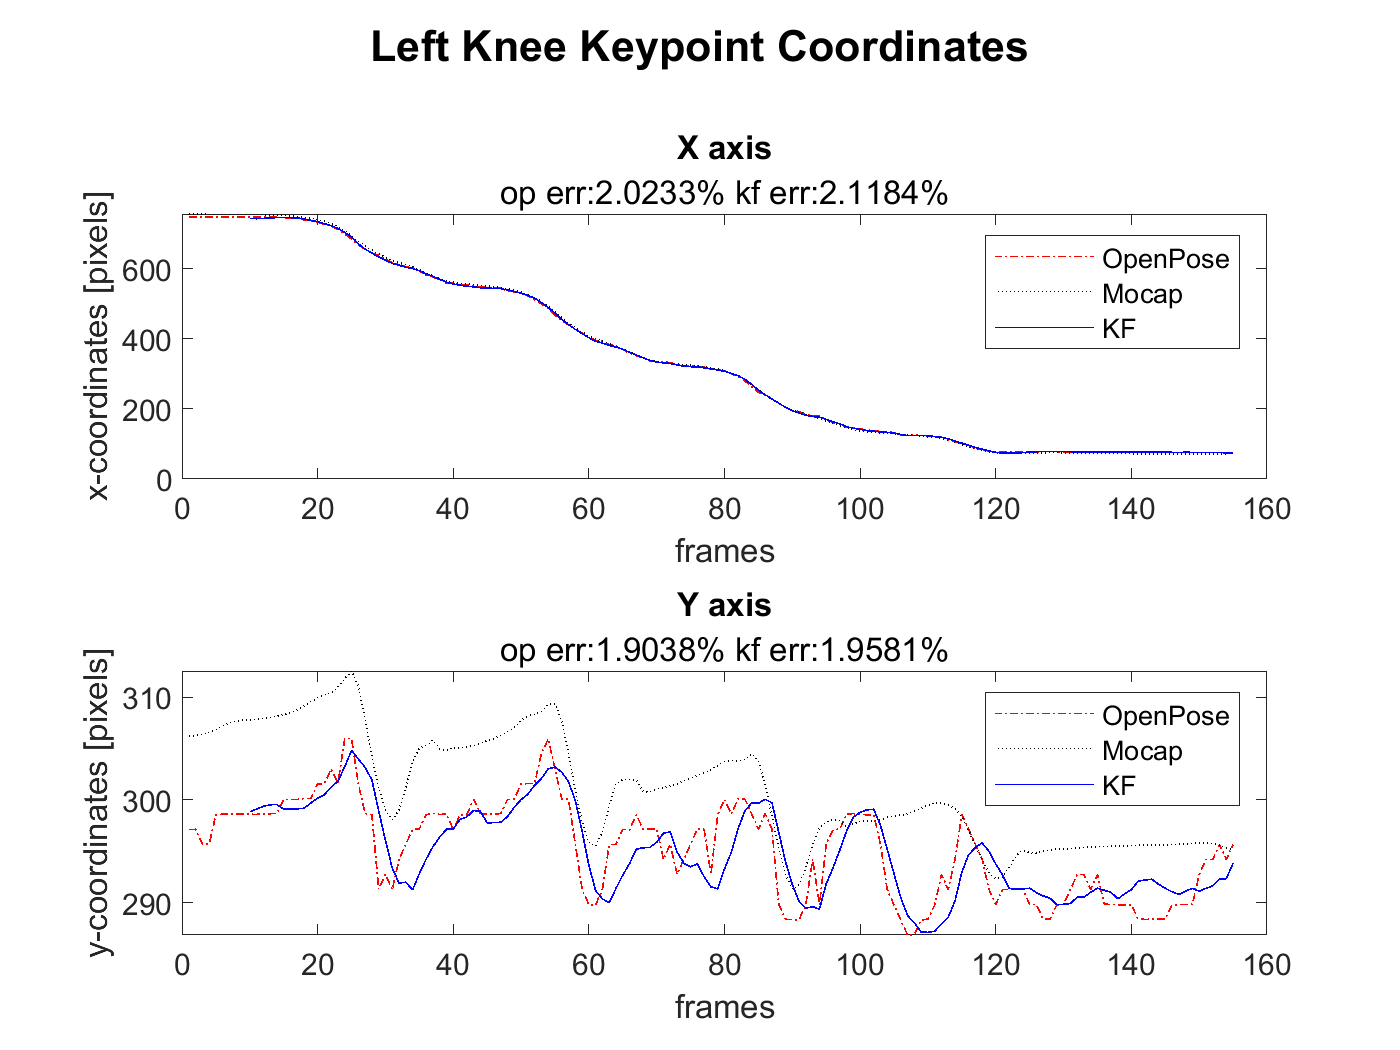

keypoint_op=[op.l_knee_x op.l_knee_y];
keypoint_mocap=[mocap.LKNE_x mocap.LKNE_y];
keypoint_kf=[kf.l_knee_x kf.l_knee_y];
kf_x=keypoint_kf(:,1);
kf_y=keypoint_kf(:,2);
op_x=keypoint_op(:,1);
op_y=keypoint_op(:,2);
mocap_x=keypoint_mocap(:,1);
mocap_y=keypoint_mocap(:,2);

%plotting
figure;
sgtitle('Left Knee Keypoint Coordinates','FontSize',13,'FontWeight','bold') 
subplot(2,1,1);
plot(op_x,'r-.')
hold on;
plot(mocap_x,'k:')
plot(start_frame:total_frame, kf_x,'b-')
legend('OpenPose', 'Mocap','KF')
all_err=(abs(op_x-mocap_x)./mocap_x)*100;
err=mean(all_err);
all_err_kf=(abs(kf_x-mocap_x(start_frame:end))./mocap_x(start_frame:end))*100;
err_kf=mean(all_err_kf);
errors_x=[errors_x; err err_kf];
subtitle("op err:"+err+"% kf err:" + err_kf +"%")
title("X axis")
xlabel('frames')
ylabel('x-coordinates [pixels]')
hold off;

subplot(2,1,2);
plot(op_y,'r-.')
hold on;
plot(mocap_y,'k:')
plot(start_frame:total_frame, kf_y,'b-')
legend('OpenPose', 'Mocap','KF')
all_err=(abs(op_y-mocap_y)./mocap_y)*100;
err=mean(all_err);
all_err_kf=(abs(kf_y-mocap_y(start_frame:end))./mocap_y(start_frame:end))*100;
err_kf=mean(all_err_kf);
errors_y=[errors_y; err err_kf];
subtitle("op err:"+err+"% kf err:" + err_kf +"%")
xlabel('frames')
title("Y axis")
ylabel('y-coordinates [pixels]')
hold off;

f = gcf;
fig_filename='figures\' + subject +'_'+ comparison_mode+'_l-knee.png';
exportgraphics(f,fig_filename,'Resolution',300)

Left ankle

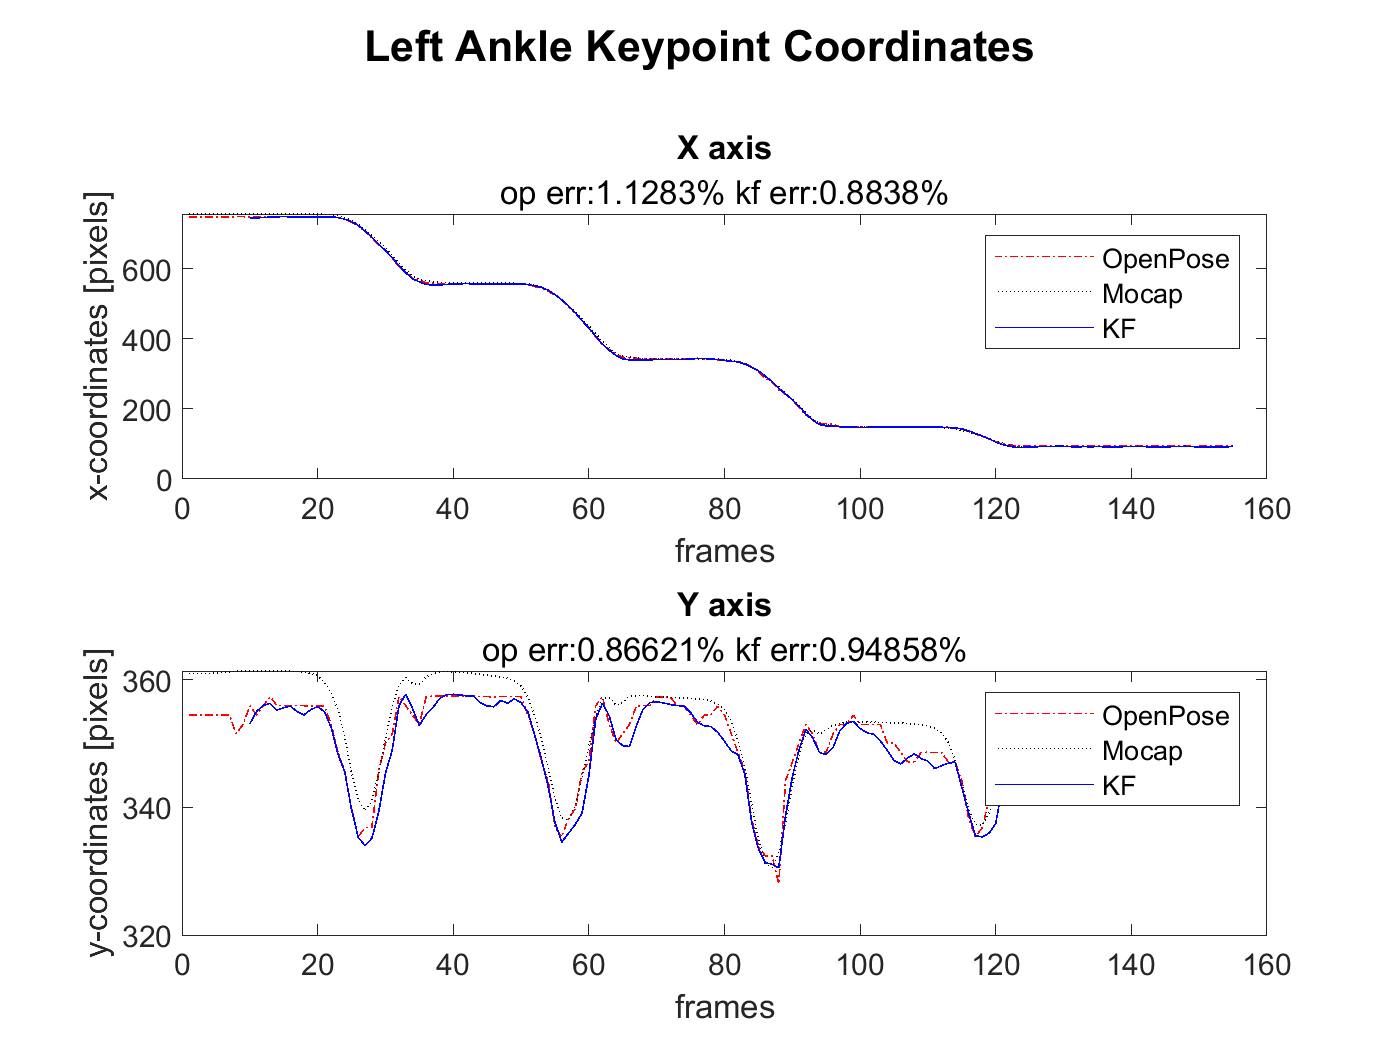

keypoint_op=[op.l_ankle_x op.l_ankle_y];
keypoint_mocap=[mocap.LANK_x mocap.LANK_y];
keypoint_kf=[kf.l_ankle_x kf.l_ankle_y];
kf_x=keypoint_kf(:,1);
kf_y=keypoint_kf(:,2);
op_x=keypoint_op(:,1);
op_y=keypoint_op(:,2);
mocap_x=keypoint_mocap(:,1);
mocap_y=keypoint_mocap(:,2);

%plotting
figure;
sgtitle('Left Ankle Keypoint Coordinates','FontSize',13,'FontWeight','bold') 
subplot(2,1,1);
plot(op_x,'r-.')
hold on;
plot(mocap_x,'k:')
plot(start_frame:total_frame, kf_x,'b-')
legend('OpenPose', 'Mocap','KF')
all_err=(abs(op_x-mocap_x)./mocap_x)*100;
err=mean(all_err);
all_err_kf=(abs(kf_x-mocap_x(start_frame:end))./mocap_x(start_frame:end))*100;
err_kf=mean(all_err_kf);
errors_x=[errors_x; err err_kf];
subtitle("op err:"+err+"% kf err:" + err_kf +"%")
title("X axis")
ylabel('x-coordinates [pixels]')
xlabel('frames')
hold off;

subplot(2,1,2);
plot(op_y,'r-.')
hold on;
plot(mocap_y,'k:')
plot(start_frame:total_frame, kf_y,'b-')
legend('OpenPose', 'Mocap','KF')
all_err=(abs(op_y-mocap_y)./mocap_y)*100;
err=mean(all_err);
all_err_kf=(abs(kf_y-mocap_y(start_frame:end))./mocap_y(start_frame:end))*100;
err_kf=mean(all_err_kf);
errors_y=[errors_y; err err_kf];
subtitle("op err:"+err+"% kf err:" + err_kf +"%")
xlabel('frames')
ylabel('y-coordinates [pixels]')
title("Y axis")
hold off;

f = gcf;
fig_filename='figures\' + subject +'_'+ comparison_mode+'_l-ankle.png';
exportgraphics(f,fig_filename,'Resolution',300)

Left heel

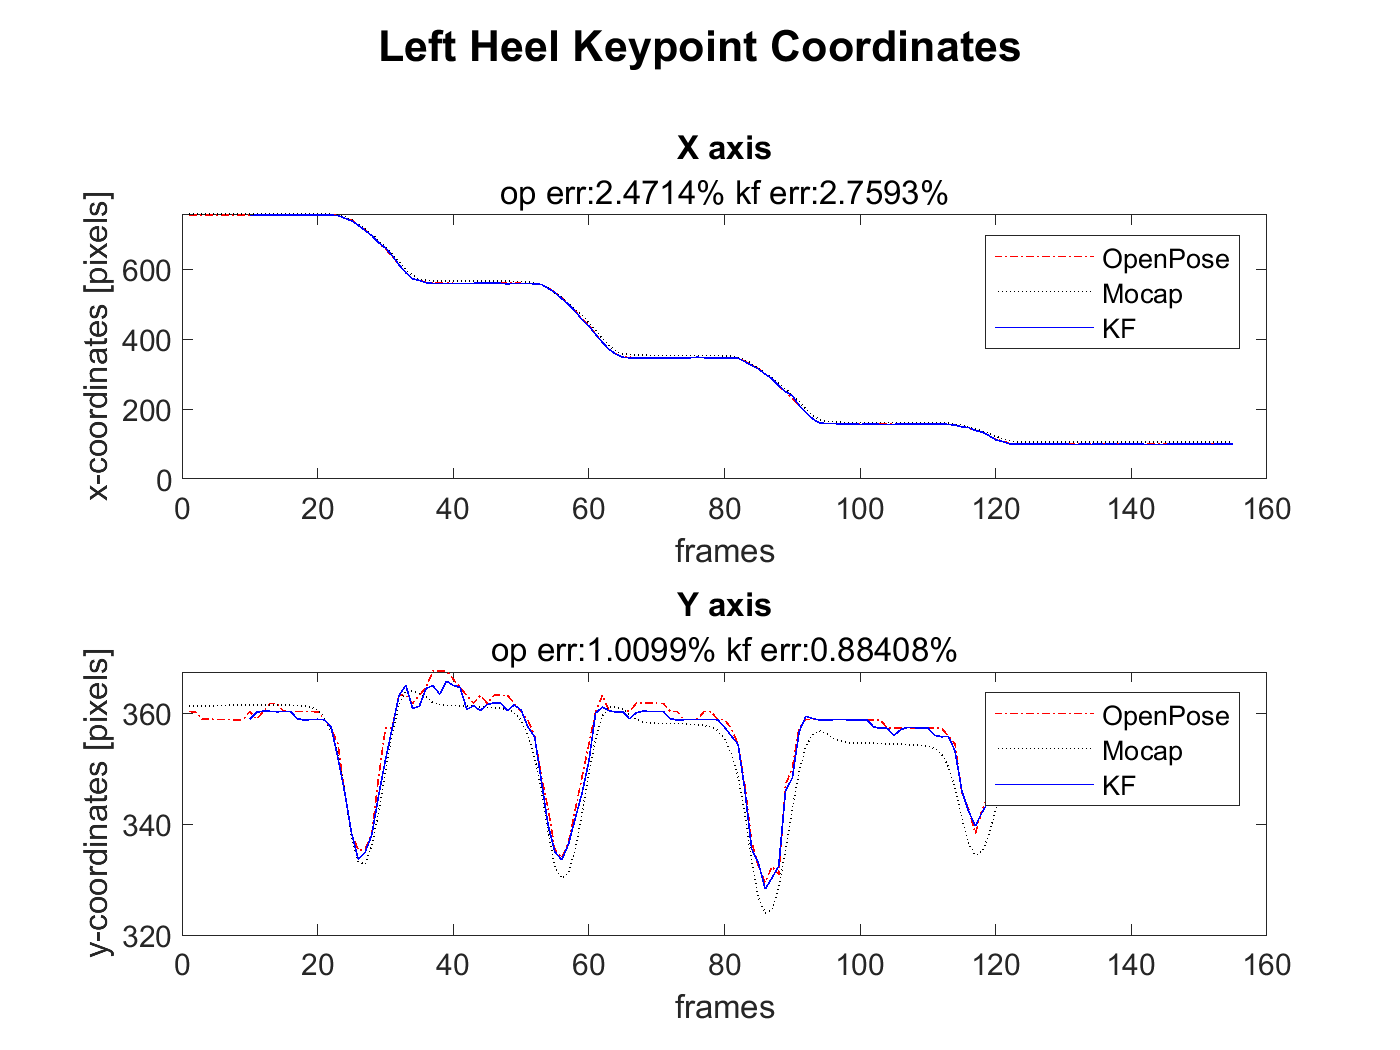

keypoint_op=[op.l_heel_x op.l_heel_y];
keypoint_mocap=[mocap.LHEE_x mocap.LHEE_y];
keypoint_kf=[kf.l_heel_x kf.l_heel_y];
kf_x=keypoint_kf(:,1);
kf_y=keypoint_kf(:,2);
op_x=keypoint_op(:,1);
op_y=keypoint_op(:,2);
mocap_x=keypoint_mocap(:,1);
mocap_y=keypoint_mocap(:,2);

%plotting
figure;
sgtitle('Left Heel Keypoint Coordinates','FontSize',13,'FontWeight','bold')  
subplot(2,1,1);
plot(op_x,'r-.')
hold on;
plot(mocap_x,'k:')
plot(start_frame:total_frame, kf_x,'b-')
legend('OpenPose', 'Mocap','KF')
all_err=(abs(op_x-mocap_x)./mocap_x)*100;
err=mean(all_err);
all_err_kf=(abs(kf_x-mocap_x(start_frame:end))./mocap_x(start_frame:end))*100;
err_kf=mean(all_err_kf);
errors_x=[errors_x; err err_kf];
subtitle("op err:"+err+"% kf err:" + err_kf +"%")
title("X axis")
xlabel('frames')
ylabel('x-coordinates [pixels]')
hold off;

subplot(2,1,2);
plot(op_y,'r-.')
hold on;
plot(mocap_y,'k:')
plot(start_frame:total_frame, kf_y,'b-')
legend('OpenPose', 'Mocap','KF')
all_err=(abs(op_y-mocap_y)./mocap_y)*100;
err=mean(all_err);
all_err_kf=(abs(kf_y-mocap_y(start_frame:end))./mocap_y(start_frame:end))*100;
err_kf=mean(all_err_kf);
errors_y=[errors_y; err err_kf];
subtitle("op err:"+err+"% kf err:" + err_kf +"%")
xlabel('frames')
ylabel('y-coordinates [pixels]')
title("Y axis")
hold off;

f = gcf;
fig_filename='figures\' + subject +'_'+ comparison_mode+'_l-heel.png';;
exportgraphics(f,fig_filename,'Resolution',300)

Table

keypoint_names=transpose(["neck-clav" "neck" "spine-hip" "r-hip" "r-knee" "r-ankle" "r-heel" "l-hip" "l-knee" "l-ankle" "l-heel"]);

all_errors = table(keypoint_names,errors_x(:,1),errors_x(:,2),errors_x(:,1)-errors_x(:,2),errors_y(:,1),errors_y(:,2),errors_y(:,1)-errors_y(:,2),'VariableNames',{'keypoint','x-op','x-kf','x diff','y-op','y-kf' 'y diff'})

all_errors = 11×7 table
     keypoint       x-op       x-kf       x diff       y-op       y-kf       y diff  
    ___________    _______    _______    _________    _______    _______    _________

    "neck-clav"     6.5565      6.609    -0.052539     4.0839     4.0421     0.041787
    "neck"         0.99578    0.93105     0.064733     1.2899     1.2637     0.026157
    "spine-hip"     6.7195     3.8636       2.8559     4.5594     4.2632      0.29623
    "r-hip"         5.2878     2.9357       2.3521     4.7467      4.532      0.21468
    "r-knee"        3.2266     3.5132     -0.28663     1.1598     1.0743     0.085549
    "r-ankle"       1.7529     2.1917     -0.43881     1.8396     1.6655      0.17415
    "r-heel"         1.984     2.0441    -0.06007


table_filename="errors\labeled_" + subject +"_"+comparison_mode+".csv";
writetable(all_errors,table_filename)

table_filename="errors\" + subject +"_"+comparison_mode+".csv";
writetable(all_errors(:,2:end),table_filename)

% % Loop through figures 2:end
% for i = 2:numel(figHandles)
%  export_fig(fn, '-pdf', figHandles(i), '-append')
% end
% 
% FolderName = tempdir;   % Your destination folder
% FigList = findobj(allchild(0), 'flat', 'Type', 'figure');
% for iFig = 1:length(FigList)
%   FigHandle = FigList(iFig);
%   FigName   = num2str(get(FigHandle, 'Number'));
%   set(0, 'CurrentFigure', FigHandle);
%   savefig(fullfile(FolderName, [FigName '.fig']));
% end